# Distance Matrix Correctness and Benchmarks

Cooper Brown

dmatref = @distancematrix_ref;
dmat = @distancematrix;
dmatf = @distancematrixf;

format longe

## Correctness

We compare against `dmatref`.

### Matlab, asymmetric case

err = 0;
for dim = [1, 2, 3, 10, 20, 30, 100]
    for N = [40, 400, 4000]
        dsites = CreatePoints(N, dim, 'r');
        cntrs = CreatePoints(N, dim, 'r');
        res = dmat(dsites, cntrs);
        resref = dmatref(dsites, cntrs);
        err = err + sum(abs(res - resref), 'all');
    end
end
disp(err);

     2.195950132843905e-08



### Matlab, symmetric case

err = 0;
for dim = [1, 2, 3, 10, 20, 30, 100]
    for N = [40, 400, 4000]
        pts = CreatePoints(N, dim, 'r');
        res = dmat(pts);
        resref = dmatref(pts, pts);
        err = err + sum(abs(res - resref), 'all');
    end
end
disp(err);

     3.969944788233355e-04



### Fortran, asymmetric case

err = 0;
for dim = [1, 2, 3, 10, 20, 30, 100]
    for N = [40, 400, 4000]
        dsites = CreatePoints(N, dim, 'r');
        cntrs = CreatePoints(N, dim, 'r');
        resf = dmatf(dsites, cntrs);
        resref = dmatref(dsites, cntrs);
        err = err + sum(abs(resf - resref), 'all');
    end
end
disp(err);

     0



### Fortran, symmetric case

err = 0;
for dim = [1, 2, 3, 10, 20, 30, 100]
    for N = [40, 400, 4000]
        pts = CreatePoints(N, dim, 'r');
        resf = dmatf(pts);
        resref = dmatref(pts, pts);
        err = err + sum(abs(resf - resref), 'all');
    end
end
disp(err);

     1.798877046264925e-04



## Benchmarks

We estimate the computational complexities.

### Dimensionality runtime, asymmetric

% Settings for the benchmark
dim = 2.^(0:14);
N = 100;
ntrials = 1000;

% For the reference implementation
tref = getrt('d', dim, N, ntrials, dmatref);

% For the MATLAB implementation
t = getrt('d', dim, N, ntrials, dmat);

% For the Fortran implementation
tf = getrt('d', dim, N, ntrials, dmatf);

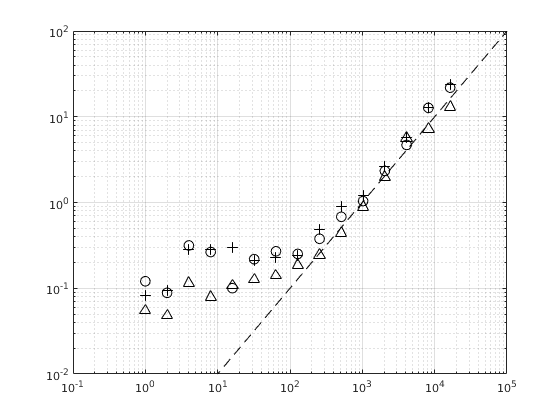

figure;
loglog(dim, tref, 'ok', 'Markersize', 9);
hold on;
loglog(dim, t, '+k', 'Markersize', 9);
loglog(dim, tf, '^k', 'Markersize', 9);
fplot(@(x) 10^-3*x, '--k');
axis(10.^[-1, 5, -2, 2]);
grid on;

### Number of points runtime, asymmetric

% Settings for the benchmark
dim = 3;
N = 2.^(2:11);
ntrials = 1000;

% For the reference implementation
tref = getrt('n', dim, N, ntrials, dmatref);

% For the MATLAB implementation
t = getrt('n', dim, N, ntrials, dmat);

% For the Fortran implementation
tf = getrt('n', dim, N, ntrials, dmatf);

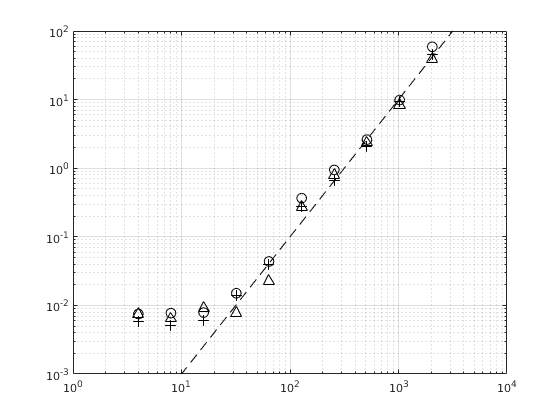

figure;
loglog(N, tref, 'ok', 'Markersize', 9);
hold on;
loglog(N, t, '+k', 'Markersize', 9);
loglog(N, tf, '^k', 'Markersize', 9);
fplot(@(x) 10^-5*x.^2, '--k');
axis(10.^[0, 4, -3, 2]);
grid on;

## Auxilary Functions

function t = getrt(type, d, N, ntrials, method)
    if type == 'd'
        nt = length(d);
    else
        nt = length(N);
    end
    t = zeros(nt, 1);
    for j = 1:nt
        if type == 'd'
            dsites = CreatePoints(N, d(j), 'r');
            cntrs = CreatePoints(N, d(j), 'r');
        else
            dsites = CreatePoints(N(j), d, 'r');
            cntrs = CreatePoints(N(j), d, 'r');
        end
        for k = 1:ntrials
            tic;
            res = method(dsites, cntrs);
            t(j) = t(j) + toc;
        end
    end
end